clearvars
close all
clc



%% load audio
[x,Fs] = audioread('hw2_buongiorno.wav');
T = 1/Fs;
Nx = length(x);

sound(x,Fs);

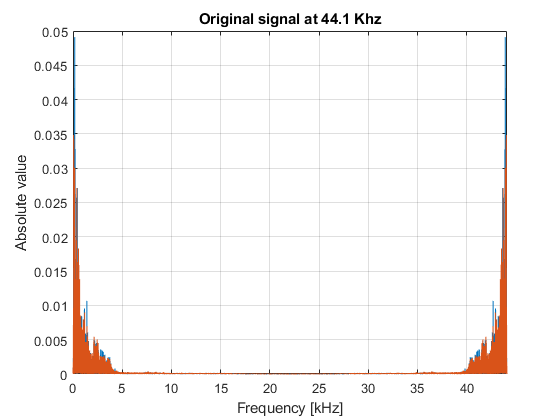


fx = (0:Nx-1)/(Nx*T);
X = T*fft(x);
% show absolute value in frequency
plot(fx/1e3,(abs(X)));
grid;
xlabel('Frequency [kHz]'); xlim([0 Fs/1e3]);
ylabel('Absolute value');
title('Original signal at '+ string(Fs/1e3) +' Khz');

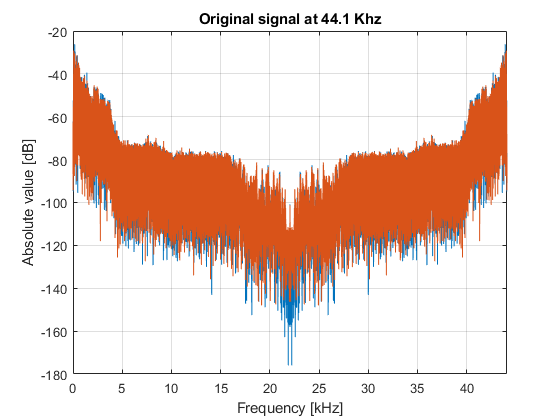


plot(fx/1e3,20*log10(abs(X)));
grid;
xlabel('Frequency [kHz]'); xlim([0 Fs/1e3]);
ylabel('Absolute value [dB]');
title('Original signal at '+ string(Fs/1e3) +' Khz');

#### Rate conversion

% sampling freq. output signal: Fs1 = (L/M)*Fs
L = 160;
M = 147;

T2 = T/L;
T1 = M*T2;
Fs2 = 1/T2;
Fs1 = 1/T1;

#### Interpolation


Nv = L*Nx;
v = zeros(Nv,2); % interpolated signal
for l=0:Nx-1
    v(l*L+1,:) = L*x(l+1,:);
end


#### Filtering

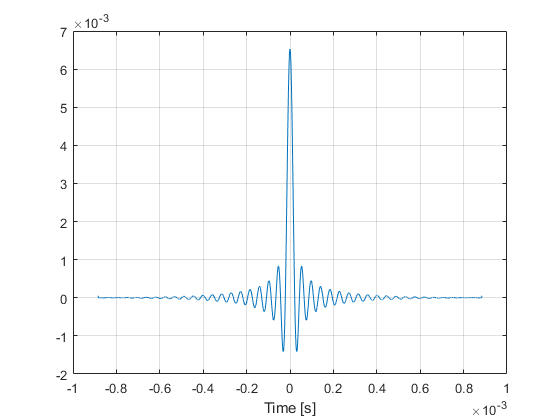

f0 = Fs/2;

al = 0.1; % transition bandwidth in percentage
fp = f0; % pass band upper limit
fs = f0*(1+al); % stop band lower limit

[NN,Fo,Ao,W] = firpmord([fp fs],[1 0],[1e-3 1e-4],Fs2);
h0 = firpm(NN,Fo,Ao,W);
tt = T2*(-NN/2:NN/2);
plot(tt,h0); grid;
xlabel("Time [s]");

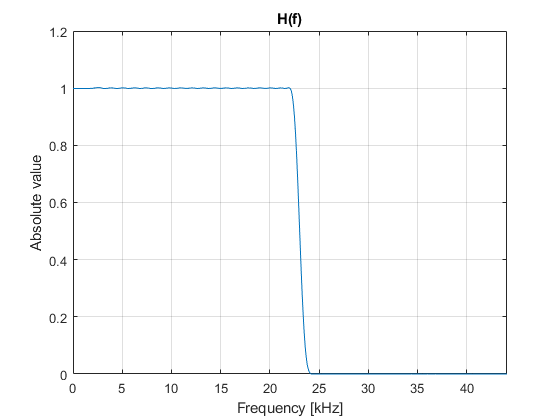

% behaviour in frequency obtained by use of function freqz
[H0,ff] = freqz(h0,1,8*(NN+1),Fs2);
plot(ff/1e3,abs(H0)); grid; 
xlim([0,Fs/1e3]);
xlabel("Frequency [kHz]");
ylabel("Absolute value");
title("H(f)");

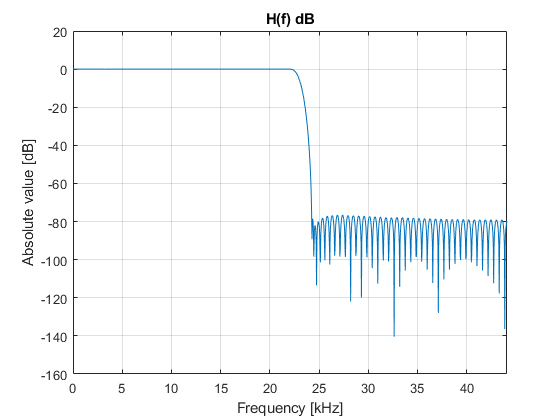

plot(ff/1e3,20*log10(abs(H0))); grid; 
xlim([0,Fs/1e3]);
xlabel("Frequency [kHz]");
ylabel("Absolute value [dB]");
title("H(f) dB");

z = [conv(v(:,1),h0), conv(v(:,2),h0)];
Nz = length(z);
fz = (0:Nz-1)/(Nz*Fs2);

#### Decimation

Ny = ceil(Nz/M);
y = z(1:M:end,:);

sound(y,Fs1);

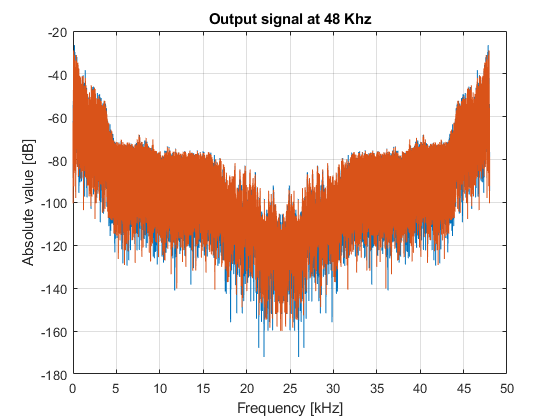

fy = (0:Ny-1)/(Ny*T1);
Y = T1*fft(y);
% show absolute value in frequency
plot(fy/1e3,20*log10(abs(Y)));
grid;
xlabel('Frequency [kHz]'); 
ylabel('Absolute value [dB]');
title('Output signal at '+ string(Fs1/1e3) +' Khz');